# Trajectory Generation

## Load the map

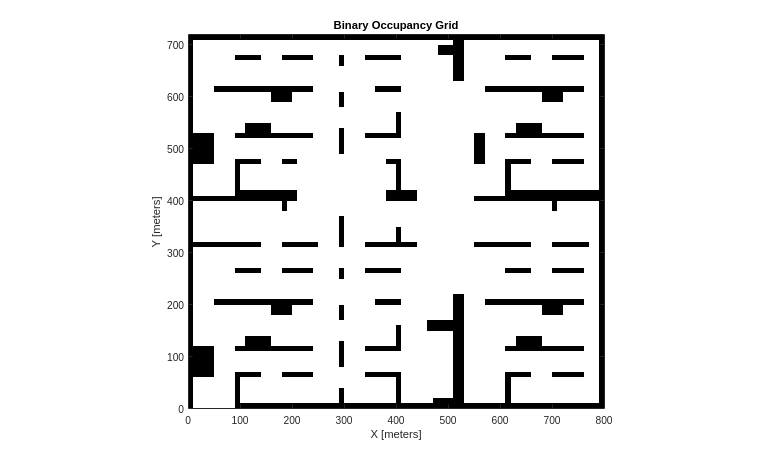

map = load('trajectories/bigmap.mat').map;
% save('trajectories/bigmap', 'map')
resolution = .1;
radius = 2;
map = binaryOccupancyMap(map,resolution);
map2 = binaryOccupancyMap(map,resolution);
inflate(map2,radius);
show(map)

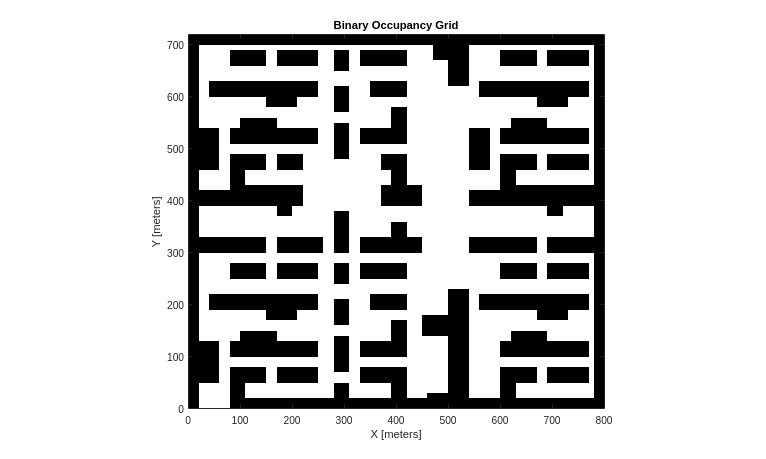

show(map2)

## Create waypoints

start = [50 25];

p1 = [140 90];
p2 = [125 180];
p3 = [250 40];
p4 = [340 155];
p5 = [315 225];
p6 = [190 360];
p7 = [75 290];
p8 = [140 380];
p9 = [290 290];
p10 = [40 140];
p11 = [320 160];
p12 = [440 50];
p13 = [200 230];
p14 = [435 210];
p15 = [260 275];
p16 = [295 60];
p17 = [370 370];
p18 = [390 240];
p19 = [110 240];
p20 = [260 140];
p21 = [100 350];
p22 = [220 360];
wp = [
    480 400;
    280 420;
    510 580;
    490 475;
    540 440;
    420 645;
    440 595;
    450 540;
    275 390;
    240 470;
    340 460;
    470 300;
    480 340;
    520 350;
    500 245;
    550 260;
    555 140;
    560 100;
    660 90;
    590 350;
    670 340;
    60 690;
    90 580;
    220 560;
    655 235;
    760 650;
    680 680;
    590 670;
    570 580;
    765 565;
    50 25;
    ];
all_waypoints = [p1; p2; p3; p4; p5; p6; p7; p8; p9; p10; p11; p12; p13; p14; p15; p16; p17; p18; p19; p20; p21; p22];
all_waypoints = [all_waypoints; wp];
waypoints = all_waypoints;
%save('trajectories/waypoints.mat', 'waypoints');

## Visualize map and waypoints

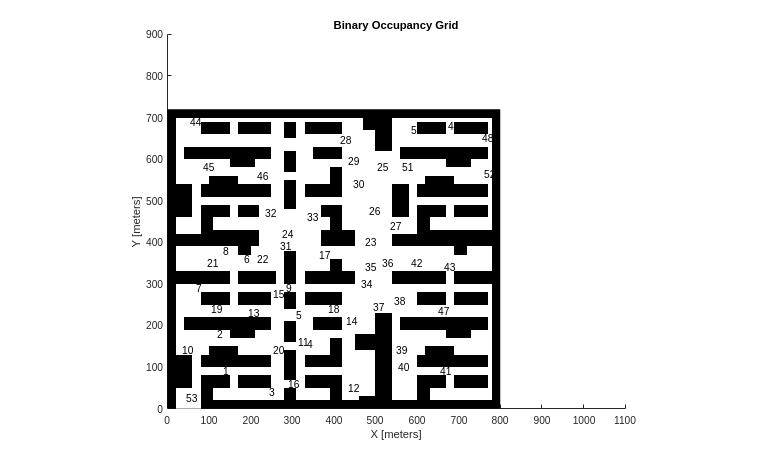

f1 = figure(1); clf;
hold on;
show(map2);
%plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(all_waypoints(:,1))
%for i = 1:length(trajectory.x_waypoints)
 %   plot(trajectory.x_waypoints(i), trajectory.y_waypoints(i), 'o', 'LineWidth', 3)
  % plot(all_waypoints(i,1), all_waypoints(i,2), 'o', 'LineWidth', 3, 'DisplayName', sprintf("p%d", i)); 
end
text(all_waypoints(:,1)-5, all_waypoints(:,2), string(1:numel(all_waypoints(:,1))));

hold off;
axis([0 1100 0 900])

%waypoints = all_waypoints([53 7 46 28 50 52 51 36 11 16 53], :);
%waypoints = all_waypoints([44 45 32 24 15 17 39 41 47 43 30 28 46 44], :);
% %waypoints = all_waypoints([12 14 42 27 30 52 48 50 28 21 9 4 12], :);
% waypoints = all_waypoints([12 16 3 1 10 2 5 9 21 24 17 32 25 51 27 42 43 37 14 12], :);
% %waypoints = all_waypoints([53 28 29 25 50 49 48 52 51 27 16 1 53], :);
% %waypoints = all_waypoints([53 1 3 16 12 14 37 39 40 41 47 43 17 6 21 7 19 2 10 53], :);
% %waypoints = all_waypoints([44 45 32 24 15 17 39 41 47 43 30 28 46 44], :);
% %waypoints = all_waypoints([44 32 31 22 8 19 1 3 5 4 14 36 23 27 28 28 44], :);
% trajectory = initialize_trajectory(prm, waypoints, velocity);
% trajectory.flight_time

ans = 1.1078e+03

% if trajectory.flight_time > 975 && trajectory.flight_time < 1225 
%     write_trajectory_data(conn, trajectory.start, trajectory.path_distance, trajectory.flight_time, trajectory.waypoints);
% end


num_nodes = 8000;
conn_dist = 25;

H = load('distance_matrix.mat').H;
all_waypoints = load('waypoints.mat').waypoints;

prm = mobileRobotPRM('Map', map2);
prm.NumNodes = num_nodes;
prm.ConnectionDistance = conn_dist;

num_wps = 8;
velocity = 2.5; 

c = 0;
while true
    wpidx = randperm(length(all_waypoints)-1, num_wps);
    s = length(all_waypoints);
    wp = [s];
    dist = 0;
    while ~isempty(wpidx)
        [d, idx] = sort(H(s, wpidx));
        dist = dist + d(1);
        s = wpidx(idx(1));
        wp = [wp s];
        wpidx(idx(1)) = [];
    end
    wpidx = length(all_waypoints);
    [d, idx] = sort(H(s, wpidx));
    dist = dist + d(1);
    s = wpidx(idx(1));
    wp = [wp s];
    waypoints = all_waypoints(wp,:);
    if dist > 260 && dist < 310
        trajectory = initialize_trajectory(prm, waypoints, velocity);
        trajectory.poi = wp;
        if trajectory.flight_time > 975 && trajectory.flight_time < 1225 
            write_trajectory_data(conn, trajectory.start, trajectory.path_distance, trajectory.flight_time, trajectory.waypoints);
            c = c + 1;
            disp(c)
            if c == 6
                break
            end
        end
    end
end

     1

     2

     3

     4

     5

     6



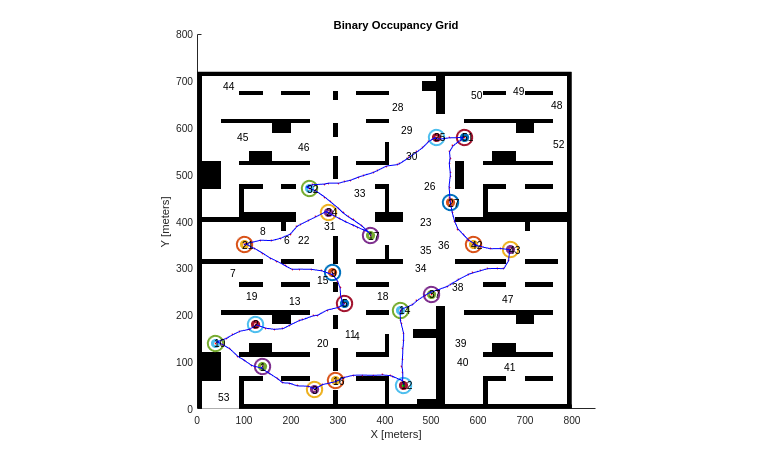



f1 = figure(1); clf;
f1.Position = [1 1 1000 600];
%subplot(2,2, [1; 3]);
hold on;
show(map);
%plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
%for i = 1:length(trajectory.x_waypoints)
 %   plot(trajectory.x_waypoints(i), trajectory.y_waypoints(i), 'o', 'LineWidth', 3)
   plot(waypoints(i,1), waypoints(i,2), 'o', 'Markersize', 15, 'LineWidth', 2, 'DisplayName', sprintf("p%d", i)); 
end
plot(trajectory.path(:,1), trajectory.path(:,2), 'r.', 'MarkerSize', 5)
plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(trajectory.waypoints(:,1))
   plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(trajectory.path)-1
    plot([trajectory.path(i-1,1) trajectory.path(i, 1)], [trajectory.path(i-1,2) trajectory.path(i, 2)], 'b');
end
text(all_waypoints(:,1)-5, all_waypoints(:,2), string(1:numel(all_waypoints(:,1))));
%plot(current_location(1), current_location(2), 'x', 'MarkerFaceColor', 'red', 'markersize', 17, 'LineWidth', 5, 'DisplayName', sprintf("p%d", i)); 
axis([0 850 0 800])
hold off;


% subplot(2,2,2);
% title("velocity profile")
% plot(trajectory.velocity_profile(3,:));
% ylabel('Velocity');
% 
% subplot(2,2,4);
% title("acceleration profile")
% plot(trajectory.acceleration_profile(3,:));
% ylabel('Acceleration');

write_trajectory_data(conn, trajectory.start, trajectory.path_distance, trajectory.flight_time, trajectory.waypoints)

desiredVelocity = 2.5; % m/s
max_vel = 7;
max_accel = 3;
path = trajectory.path;
path_distance = calculatedistance(path) % total distance to be covered

path_distance = 2.5994e+03

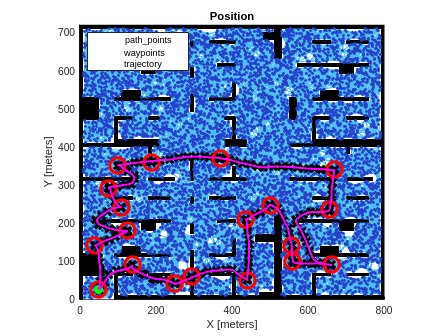

time_interval = calculatetime(path_distance,desiredVelocity); 

arrival_times = zeros(length(path),1);
for i=1:length(path)-1
    dist = calculatedistance(path(i:i+1,1:2));
    t = calculatetime(dist, desiredVelocity);
    arrival_times(i+1) = arrival_times(i) + t(2)*1.0;
end

% generate smooth time stamped trajectory
sampletimetraj=1; 
tSamples = 1:sampletimetraj:time_interval(2);
path_time = time_interval(2)/60;
numsamples = round(path_time*60/2);
%Compute minimum snap trajectories. The function outputs the trajectory positions (q), velocity (qd), acceleration (qdd), jerks (qddd), and snaps (qdddd) at the given number of samples.

% [q1,qd1,qdd1,qddd1,qdddd1,pp1,timepoints,tsamples] = minsnappolytraj(path',arrival_times',numsamples);
% [q2,qd2,qdd2,qddd,pp2,timepoints,tsamples] = minjerkpolytraj(path',arrival_times',numsamples);
%[q,qd,qdd,pp] = quinticpolytraj(path',arrival_times',tSamples);
[q,qd,qdd,pp] = bsplinepolytraj(path',time_interval,tSamples);

qd(3,:) = sqrt(qd(1,:).^2 + qd(2,:).^2);
qdd(3,:) = sqrt(qdd(1,:).^2 + qdd(2,:).^2);

x_ref_points = q(1,:)';
y_ref_points = q(2,:)';

vellim = [-max_vel max_vel; -max_vel max_vel]; 
accellim = [-max_accel max_accel; -max_accel max_accel];



f2 = figure(2); clf;


%subplot(3,2,[1,3,5]);


hold on;
prm.Map = map;
show(prm);
% plot(tInfo.Waypoints(:,1),tInfo.Waypoints(:,2),'k*')
h = zeros(1,7);
h(1) = plot(path(:,1), path(:,2), 'kx', 'MarkerSize', 10, 'linewidth', 3, 'DisplayName', 'path\_points');
h(2) = plot(waypoints(:,1), waypoints(:,2), 'ro', 'markersize', 15, 'linewidth', 3, 'displayname', 'waypoints');
%plot(path(:,1), path(:,2), 'r.', 'MarkerSize', 5)
% for i = 1:length(waypoints(:,1))
%    plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
% end
% for i = 2:length(path-1)
%     plot([path(i-1,1) path(i, 1)], [path(i-1,2) path(i, 2)], 'b');
% end
h(3) = plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
h(4) = plot(x_ref_points, y_ref_points, 'm-', 'LineWidth', 2, 'displayname', 'trajectory');
% h(5) = plot(x1_ref_points, y1_ref_points, 'c-', 'LineWidth', 2, 'displayname', 'minsnap');
% h(6) = plot(x2_ref_points, y2_ref_points, 'g-', 'LineWidth', 2, 'displayname', 'minjerk');

hold off;
title("UAV Flight Path and Waypoints")

title('Position')
%axis([0,500,0,400])
%daspect([1 1 1])
legend([h(1) h(2) h(4)], 'location', 'northwest');

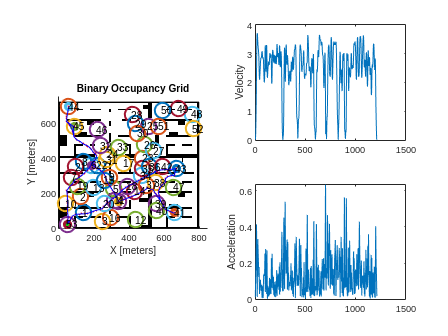

map = load('trajectories/bigmap.mat').map;
% save('trajectories/bigmap', 'map')
resolution = .1;
radius = 2;
map = binaryOccupancyMap(map,resolution);
map2 = binaryOccupancyMap(map,resolution);
inflate(map2,radius);


trajectory_tb = readtable('trajectories/trajectories_exported.csv');
trajectory_tb = trajectory_tb(trajectory_tb.path_time < 1300, :);
trajectory_tb = trajectory_tb(trajectory_tb.path_time > 950, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend');
for i = 1:height(trajectory_tb)
    trajectory = get_trajectory(trajectory_tb, i);

    figure;
    subplot(2,2, [1; 3]);
    title(sprintf("trajectory %d", i));
    hold on;
    show(map);
    %plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
    for i = 1:length(waypoints(:,1))
    %for i = 1:length(trajectory.x_waypoints)
     %   plot(trajectory.x_waypoints(i), trajectory.y_waypoints(i), 'o', 'LineWidth', 3)
       plot(waypoints(i,1), waypoints(i,2), 'o', 'Markersize', 15, 'LineWidth', 2, 'DisplayName', sprintf("p%d", i)); 
    end
    plot(trajectory.path(:,1), trajectory.path(:,2), 'r.', 'MarkerSize', 5)
    plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
    for i = 1:length(trajectory.waypoints(:,1))
       plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'o', 'LineWidth', 3); 
    end
    for i = 2:length(trajectory.path)-1
        plot([trajectory.path(i-1,1) trajectory.path(i, 1)], [trajectory.path(i-1,2) trajectory.path(i, 2)], 'b');
    end
    text(all_waypoints(:,1)-5, all_waypoints(:,2), string(1:numel(all_waypoints(:,1))));
    %plot(current_location(1), current_location(2), 'x', 'MarkerFaceColor', 'red', 'markersize', 17, 'LineWidth', 5, 'DisplayName', sprintf("p%d", i)); 
    axis([0 850 0 750])
    hold off;
    
    subplot(2,2,2);
    title("velocity profile")
    plot(trajectory.velocity_profile(3,:));
    ylabel('Velocity');
    
    subplot(2,2,4);
    title("acceleration profile")
    plot(trajectory.acceleration_profile(3,:));
    ylabel('Acceleration');
    break;
end

pln = plannerAStarGrid(map);
pln.GCost = 'Manhattan';
pln.HCost = 'Manhattan';

H = zeros(length(all_waypoints));
edges = [];
for i = 1:length(all_waypoints)-1

    p1 = double(uint8(all_waypoints(i,:)/10));
    p1 = [p1(2) p1(1)];
    p1(1) = map.GridSize(1) - p1(1);

    j = i+1;
    while j <= length(all_waypoints)
    
        p2 = double(uint8(all_waypoints(j,:)/10));
        p2 = [p2(2) p2(1)];
        p2(1) = map.GridSize(1) - p2(1);

        pth = plan(pln, p1, p2);
        H(i,j) = calculatedistance(pth);
        edges = [edges H(i,j)];
        j = j + 1;
    end

end


H

H =          0   14.4853   13.0711   22.8995   26.7279   41.3137   26.7279   39.6274   31.4853   12.0711   20.8995   31.6569   27.0711   34.9706   29.2426   17.2426   42.7990   31.2132   24.1421   15.2426   38.8701   38.8995   51.5269   44.0711   70.7696   59.9411   58.0122   72.8701   68.6985   63.1127   41.0711   49.0711   50.5563   41.6985   45.5269   48.7696   42.6274   48.0416   53.6274   57.6274   64.5269   55.7696   63.3553   80.5269   67.4558   58.8995   58.2132   11.4853   96.9117   90.1543
         0         0   21.8995   21.8284   21.8995   34.1421   19.0711   31.9706   24.3137   10.6569   19.8284   36.3848   19.8995   33.0711   22.0711   21.9706   35.6274   29.3137   16.4853   14.6569   31.2132   31.7279   46.1127   36.8995   63.5980   52.7696   53.7696   65.6985   61.5269   55.9411   33.8995   41.8995   43.3848   39.7990   42.4558   46.8701   40.7279   46.1421   51.7279   55.7279   62.6274   53.8701   61.4558   73.3553   60.2843   51.7279   56.3137   18.3137   89.7401   82

edges

edges =    14.4853   13.0711   22.8995   26.7279   41.3137   26.7279   39.6274   31.4853   12.0711   20.8995   31.6569   27.0711   34.9706   29.2426   17.2426   42.7990   31.2132   24.1421   15.2426   38.8701   38.8995   51.5269   44.0711   70.7696   59.9411   58.0122   72.8701   68.6985   63.1127   41.0711   49.0711   50.5563   41.6985   45.5269   48.7696   42.6274   48.0416   53.6274   57.6274   64.5269   55.7696   63.3553   80.5269   67.4558   58.8995   58.2132   11.4853   96.9117   90.1543   82.4975


A = ones(length(waypoints));
A = A - eye(size(A)).*A;
G = graph(A, string([1:1:length(waypoints)])')

G =   graph with properties:

    Edges: [1378×2 table]
    Nodes: [53×1 table]


G.Edges.Weight = edges';
save('trajectories/newgraph.mat', 'G');
save('trajectories/distance_matrix.mat', 'H');
H = H' + H;
save('trajectories/distance_matrix2.mat', 'H');


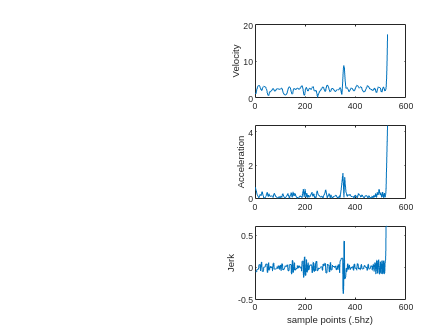


f45 = figure(45); clf;
subplot(3,2,2);
title("velocity profile")
plot(qd(3,:));
ylabel('Velocity');

subplot(3,2,4);
title("acceleration profile")
plot(qdd(3,:));
ylabel('Acceleration');


subplot(3,2,6);
title("jerk profile")
plot(diff(qdd(3,:)));
ylabel('Jerk');
xlabel('samples');